theta_max = 1.5*pi; %maximal amount of rotation is one and a half
n_steps = 1000

n_steps = 1000

offset = 0;

stepsize = 0.1e-3;
angles_frac = [0.72:stepsize:1] %angles that are going to be analyzed 

angles_frac =     0.7200    0.7201    0.7202    0.7203    0.7204    0.7205    0.7206    0.7207    0.7208    0.7209    0.7210    0.7211    0.7212    0.7213    0.7214    0.7215    0.7216    0.7217    0.7218    0.7219    0.7220    0.7221    0.7222    0.7223    0.7224    0.7225    0.7226    0.7227    0.7228    0.7229    0.7230    0.7231    0.7232    0.7233    0.7234    0.7235    0.7236    0.7237    0.7238    0.7239    0.7240    0.7241    0.7242    0.7243    0.7244    0.7245    0.7246    0.7247    0.7248    0.7249


avg_energy = zeros(1,length(angles));
avg_energy_sqr = zeros(1,length(angles));
basic_spiral = spiral(1.2,3,13,2.5); %Creating the constant force spiral object

clear best_spiral %clearing the best spiral object
lowest_avg = Inf; %setting the lowest average to infinity

for i = 1: length(angles_frac)
    logarithmic_spiral = basic_spiral.logarithmic(n_steps, theta_max, pi/2*angles_frac(i));
    logarithmic_spiral = logarithmic_spiral.complete_analysis(1000,offset);
    avg_energy(i) = mean(logarithmic_spiral.Etot);
    avg_energy_sqr(i) = mean((logarithmic_spiral.Etot).^4); 
    %taking the square to take into account negative energy values and
    %punnishing higher deviation from 0
    if avg_energy_sqr(i) <= lowest_avg
        %checking if the current average potential energy is lower than the
        %current best
        lowest_avg = avg_energy_sqr(i);
        best_spiral = logarithmic_spiral; %setting the new best potential energy 
    end
end


## Plotting the results

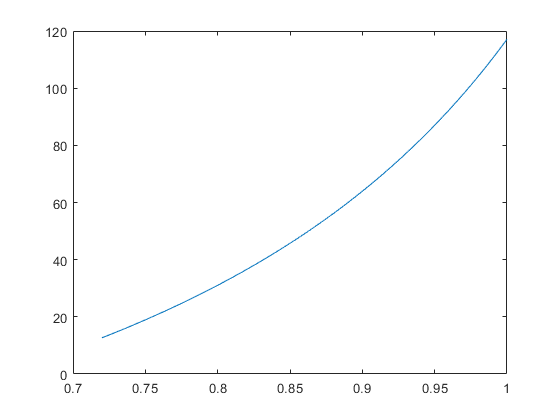

plot(angles_frac,avg_energy)

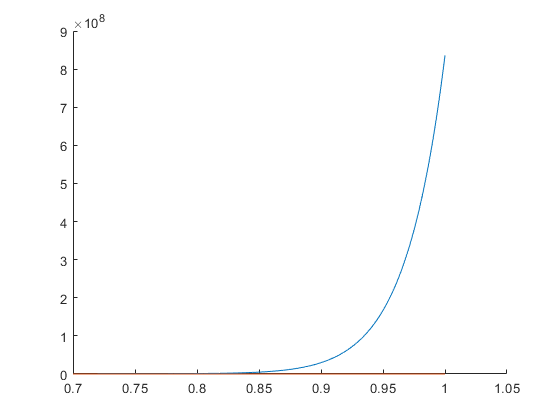

figure()
hold on
plot(angles_frac,avg_energy_sqr)
plot([0.7 1],[0 0])

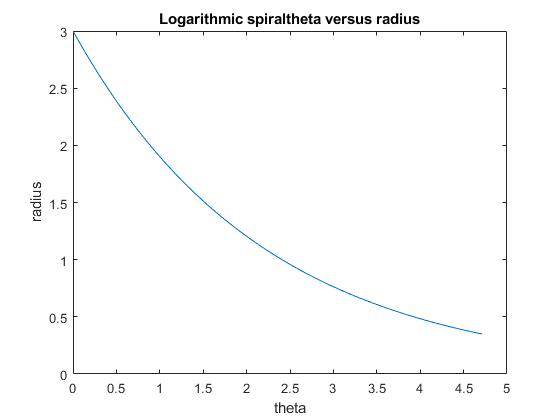

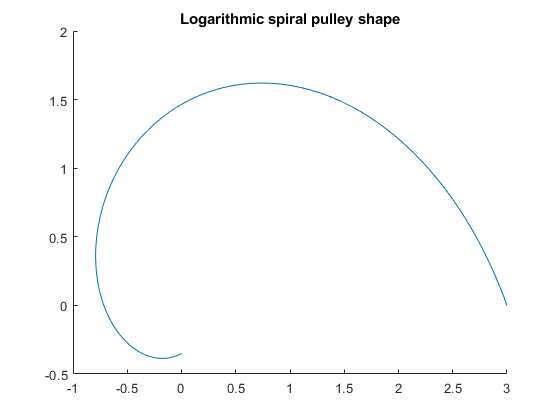

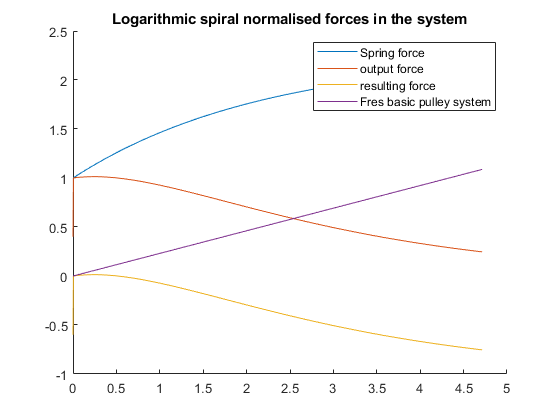

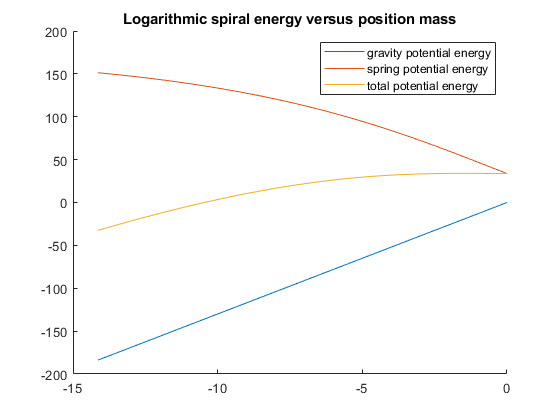

ans =   spiral with properties:

                   r1: 1.2000
                   r2: 3
                   F0: 13
                    k: 2.5000
                 name: 'Logarithmic spiral'
                    S: []
                    r: [1×1001 double]
                theta: [1×1001 double]
                    x: [1×1001 double]
                    y: [1×1001 double]
    spiral_max_stroke: 14.1372
          curve_angle: 1.1428
                 x_m2: 14.1372
                  x_m: [1×1001 double]
                  x_s: [1×1001 double]
                   rs: [1×1001 double]
                  phi: [1×1001 double]
                   Fm: [1×1001 double]
                   Fs: [1×1001 double]
                 Fres: [1×1001 double]
           Fm_control: [1×1001 double]
                   Eg: [1×1001 double]
                   Es: [1×1001 double]
                 Etot: [1×1001 double]


best_spiral.plot_all(n_steps,offset)